exctract data from microphone:

%%PARAMETERS%%
Fs = 44100; % Sample rate
recordDuration = 5;
FREQ_BIT_START = 19000;  % 19 kHz
FREQ_BIT_1 = 18000;  % 18 kHz
FREQ_BIT_STOP = 18500;  % 19 kHz
tone_length=10e-3; %length in seconds
key='AWESOMEKEY'

key = 'AWESOMEKEY'


recObj = audiorecorder(Fs, 16, 1); % 16-bit, mono recording
record(recObj);
fprintf('Recording for %d seconds...\n', recordDuration);

Recording for 5 seconds...


pause(recordDuration); % Record for the specified duration
stop(recObj);
fprintf('Done!\n');

Done!


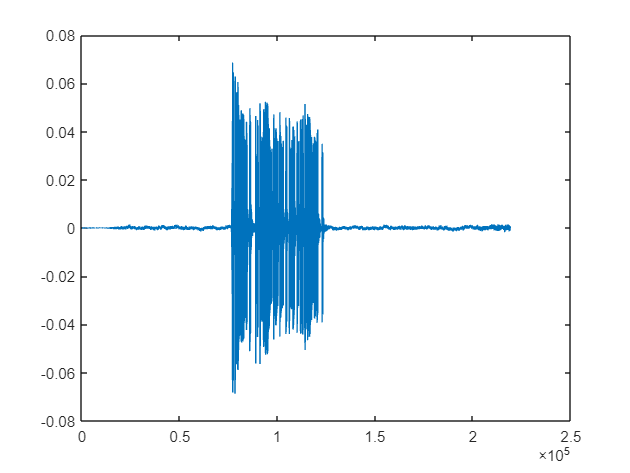

x = getaudiodata(recObj);
plot(x);

Now "x" contains all the sampled data present in the audio file. we can check the spectum of the signal with fft:


N = length(x); % Length of the audio signal
Y = fft(x);    % Compute the FFT

The prevous is the double side spectrum, we want to compute the single side spectrum:

P2 = abs(Y/N); 
magnitude = P2(1:floor(N/2+1));
magnitude(2:end-1) = 2*magnitude(2:end-1);

%Plot the FFT results
f = Fs*(0:(N/2))/N; % Frequency vector
figure;
plot(f, magnitude);
title('FFT of Audio Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
hold on; % To overlay the line on the existing plot


We can see that there is some content in frequency 18kHz and 19kHz

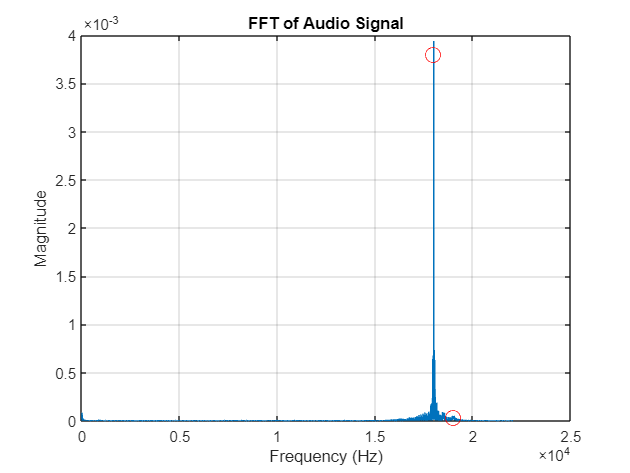


% Mark the point at the desired frequency with a red circle
[~, index] = min(abs(f - FREQ_BIT_START));
hold on;
plot(f(index), magnitude(index), 'ro', 'MarkerSize', 10); % 'ro' for red circle, adjust MarkerSize as needed
[~, index] = min(abs(f - FREQ_BIT_1));
hold on;
plot(f(index), magnitude(index), 'ro', 'MarkerSize', 10); % 'ro' for red circle, adjust MarkerSize as needed
hold off; % Release the hold on the plot

Now we can filter those frequencies and analyze the content

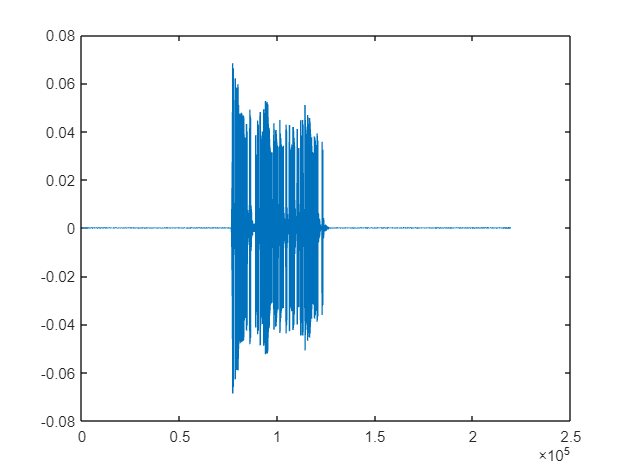

%filtering with band pass
x = bandpass(x,[0.8 0.9],'Steepness',0.85,'StopbandAttenuation',90);
N = length(x); % Length of the audio signal
plot(x);

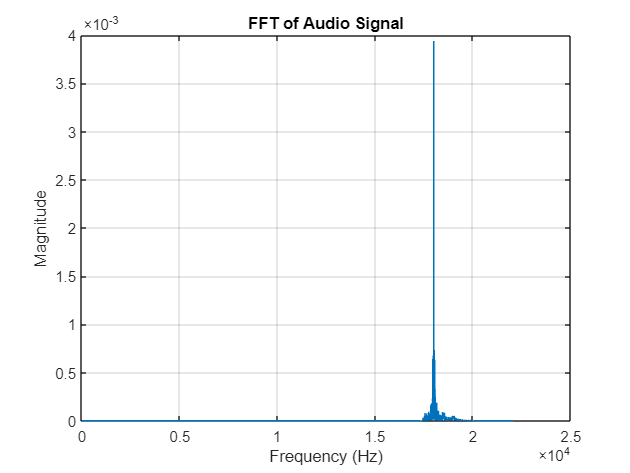

Y = fft(x);    % Compute the FFT
P2 = abs(Y/N); 
magnitude = P2(1:floor(N/2+1));
magnitude(2:end-1) = 2*magnitude(2:end-1);

%Plot the FFT results
f = Fs*(0:(N/2))/N; % Frequency vector
figure;
plot(f, magnitude);
title('FFT of Audio Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

let's compare the result using goertzel algorithm

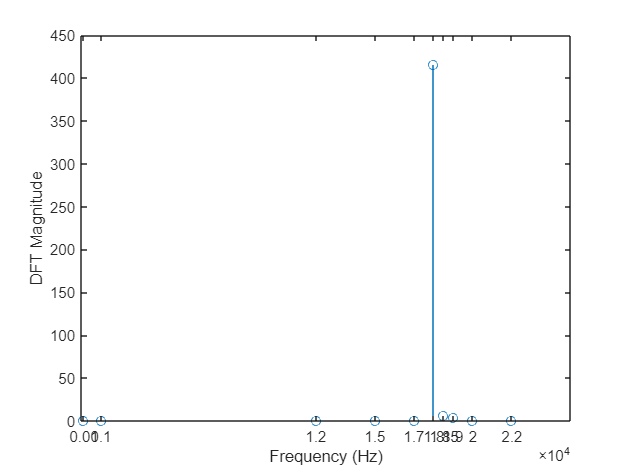

frequencies = [ 100, 1000, 12000, 15000, 17000, FREQ_BIT_1, 18500, FREQ_BIT_START,20000, 22000];
freq_indices= round(frequencies/Fs*length(x))+1;
gdft= goertzel(x, freq_indices);
stem(frequencies,abs(gdft))
ax = gca;
ax.XTick = frequencies;
% xlim(ax,[100,22000])
xlabel('Frequency (Hz)')
ylabel('DFT Magnitude')

The goertzel algorithm is more efficient in calculating the dft at determined frequency. From this dft analysis we can extract the threshold:

thr_start = abs(gdft(8))

thr_start = 4.0594

thr_stop = abs(gdft(7))

thr_stop = 5.9928

thr_bit1 = abs(gdft(6))

thr_bit1 = 416.2176

The general idea is to divide the signal into intervals and then check the presence of one or the one frequency with goertzel algorithm, but before we need to find the starting point of the comunication, to do so we can use the correlation function to find the position of bit start, by generating a reference tone signal

%reference tone signal
bitstart_tone = sin(2 * pi * FREQ_BIT_START * (0:1/Fs:tone_length - 1/Fs));
[r, lags] = xcorr(x, bitstart_tone);
plot(lags,r)


we can find the maximum correlation that corresponds to the initial time of the message

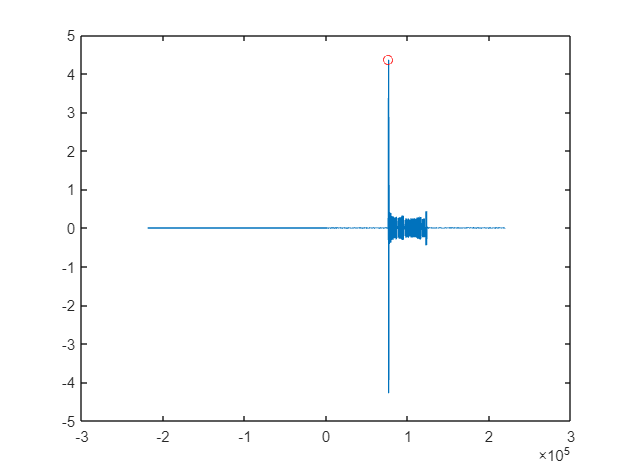

[val, max_idx] = max(abs(r));
start_idx = lags(max_idx);
hold on;
plot(max_idx-N,val, 'ro')
hold off;

With the same approach we can analyze the signal to find the stop bit

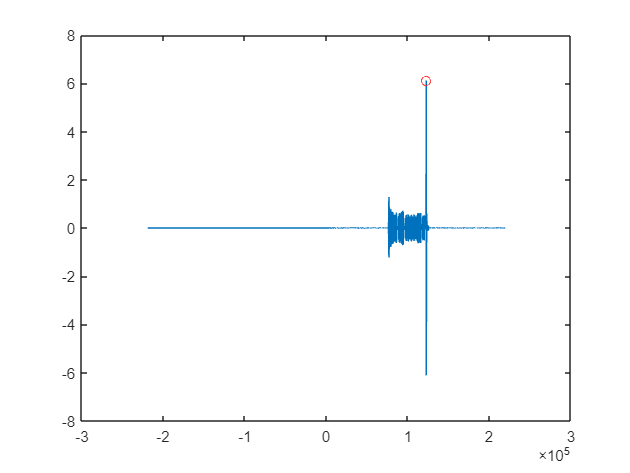

bitstop_tone = sin(2 * pi * FREQ_BIT_STOP * (0:1/Fs:tone_length - 1/Fs));
[r, lags] = xcorr(x, bitstop_tone);

plot(lags,r)
[val, max_idx] = max(abs(r));
stop_idx = lags(max_idx);
hold on;
plot(max_idx-N,val, 'ro')

Finally we can see the rappresentation of all the symbols in the signal

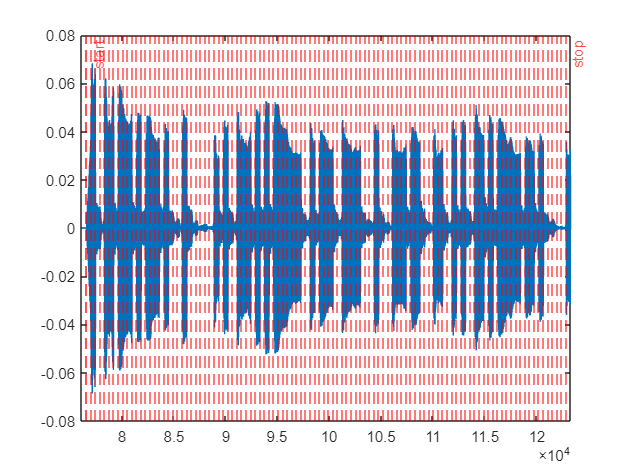

%compute the number of symbols
nseg=round((stop_idx-start_idx)/(tone_length*Fs))+1;

figure
plot(x)
hold on;
xline(start_idx, 'r--', 'LineWidth',  'Label', 'start');
for i=0:nseg-2
    xline(start_idx+i*(tone_length*Fs), 'r--');
end
xline(stop_idx, 'r--', 'LineWidth',  'Label', 'stop');
xlim([start_idx - tone_length*Fs, stop_idx+tone_length*Fs])
hold off;

Search for frequency in a block starting from the previously found index

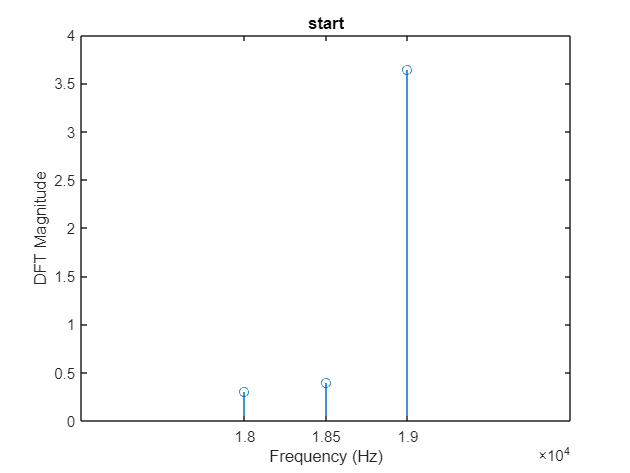

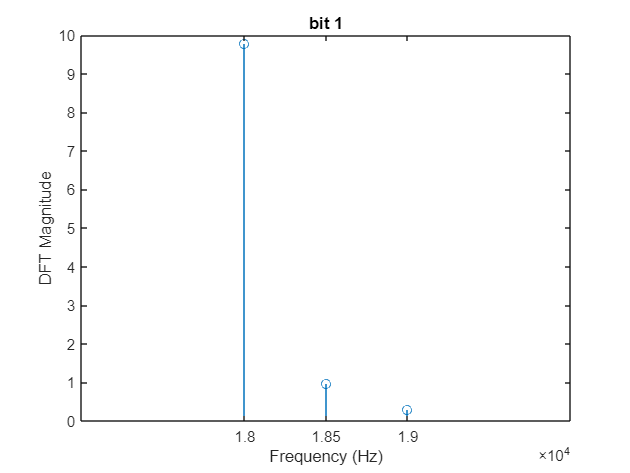

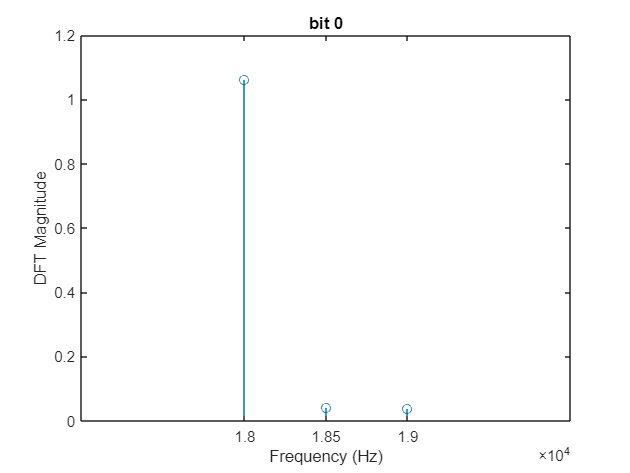

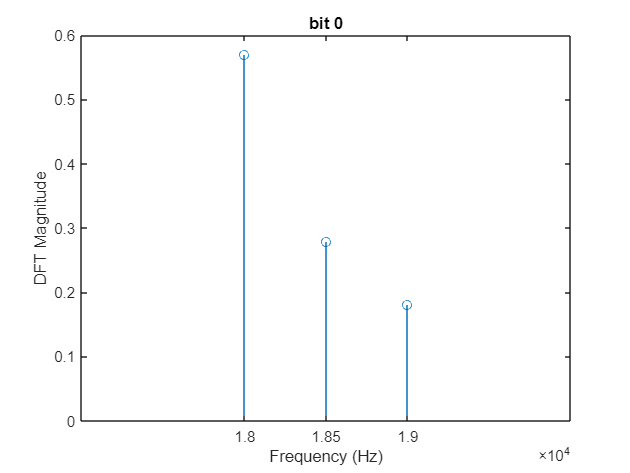

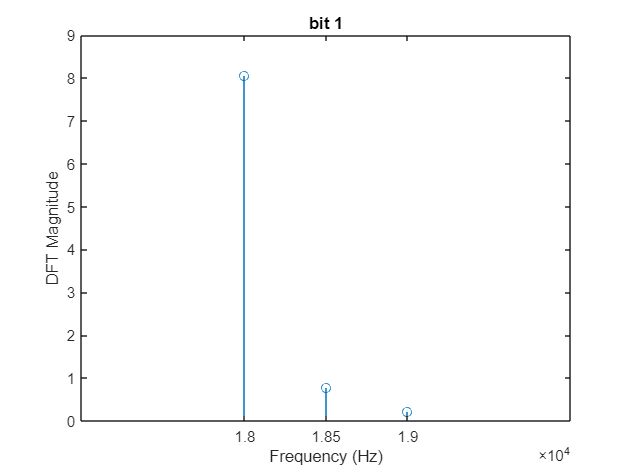

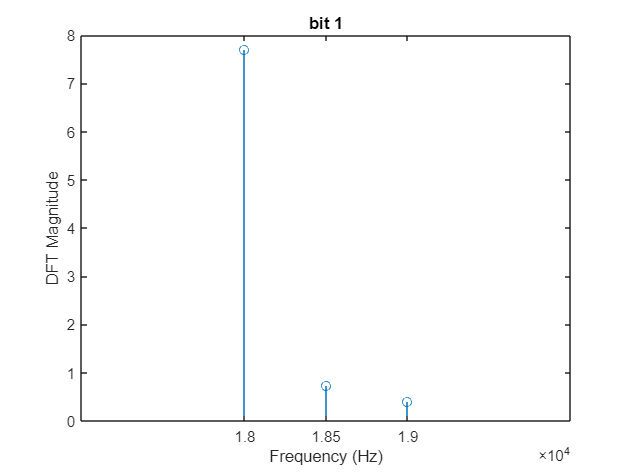

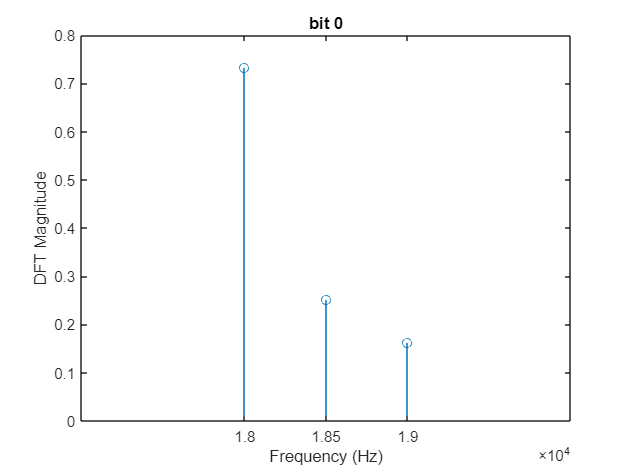

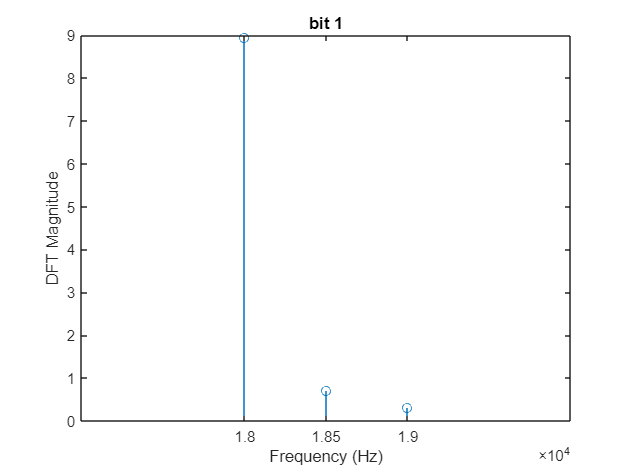

frequencies = [18000, 18500, 19000];
data="";
for i=0:nseg-1
    segment=x(start_idx+i*(tone_length*Fs):start_idx+(i+1)*(tone_length*Fs));
freq_indices = round(frequencies/Fs*length(segment))+1;
dft_data = goertzel(segment,freq_indices);
figure
bit_mag = abs(dft_data); %index 3 is start bit, 2 is stop bit, index 1 is bitdata 

if(bit_mag(3)> thr_start/2 && bit_mag(3) > bit_mag(1))
    label = "start";
    data=data.append('s');
elseif(bit_mag(1)> thr_bit1/(2*(nseg+1)) && bit_mag(1) > bit_mag(2) && bit_mag(1) > bit_mag(3))
    label = "bit 1";
    data=data.append('1');

elseif(bit_mag(2) > thr_stop/2 && bit_mag(2) > bit_mag(3) && bit_mag(2) > bit_mag(1))
    label = "stop";
    data=data.append('s');
else
    label = "bit 0";
    data=data.append('0');
end

 stem(frequencies,abs(dft_data))
 title(label)
 ax = gca;
 % ylim(ax, [0,50])
 xlim(ax, [17000,20000])
 ax.XTick = frequencies;
 xlabel('Frequency (Hz)')
 ylabel('DFT Magnitude')
end

to_process=data.extractAfter('s').extractBefore('s');
to_process=char(to_process)

to_process = '10011011101011101000100000010100111010101111110010111001111000100011101100011001010011010111110110100000'

result="";
for i=0:length(to_process)/8-1
dig=char(bin2dec(to_process(i*8+1:(i+1)*8)));
result=result.append(dig);
end
result

result = "□®□□êü¹â;□M} "

binary=to_process

binary = '10011011101011101000100000010100111010101111110010111001111000100011101100011001010011010111110110100000'

command = ['java -jar decode.jar ' binary ' ' key]

command = 'java -jar decode.jar 10011011101011101000100000010100111010101111110010111001111000100011101100011001010011010111110110100000 AWESOMEKEY'

[status, out] = system(command)

status = 0

out = '01000010001101000100000010011000010000001111010100100110000100000110001101101001011000010110111100100001'

result_decrypted="";
for i=0:length(out)/8-1
dig=char(bin2dec(out(i*8+1:(i+1)*8)));
result_decrypted=result_decrypted.append(dig);
end
result_decrypted

result_decrypted = "B4@□@õ&□ciao!"

If the string contains geolocalization data, it can be extracted analyzing the first 8 byte,  since latitude and longiude are sent as float numbers

%%Encrypted version
latitude_e = typecast(uint32(bin2dec(out(1:32))), 'single')

latitude_e = single
45.0631

longitude_e = typecast(uint32(bin2dec(out(33:64))), 'single')

longitude_e = single
7.6609

%%Not encrypted version
latitude = typecast(uint32(bin2dec(binary(1:32))), 'single')

latitude = single
-2.8874e-22

longitude =  typecast(uint32(bin2dec(binary(33:64))), 'single')

longitude = single
-1.5276e+26